### Load macrodomain outline

% Outlines of Macrodomain from ParB locus tracking
% experiments analyzed by 'ExtractRegion_HeatMap.MLX'
Domain_name = 'Terminus';

Domain_outline = load(['L:\MIGRATED\Lab_Members\' ...
    'Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\' ...
    'Figures\Fig4 elements\Macrodoamin_outline\' ...
    'No_filter\Ter_boundary.mat']).test2;


Visualize Macrodomain Mask

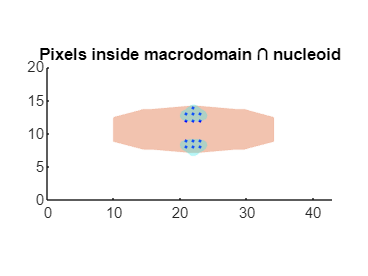

[coord_in_ori,DomCoord] =...
    FindDomainCoord(spMap,Domain_outline,...
    nuc_outline,num_pix_y,aspt_ratio,'on');


[Step_in_Domain,~] = Extract_Step_InRegion(raw_spatialDisp,...
    coord_in_ori,num_pix_y,aspt_ratio);
[Step_in_Domain_simu,~] = Extract_Step_InRegion(Simu_spatialDisp,...
    coord_in_ori,num_pix_y,aspt_ratio);

% weight ratio of macrodomain
pop_domain_ratio =...
    Pop_Domain_Ratio(5e5,acc_fit,Ro,Lo,anchor_spMap,...
    scaling_width,scaling_length,num_pix_y,aspt_ratio,...
    nuc_outline,DomCoord);

## Macrodomain viscosity

fprintf(strcat('\n==============', "  ", Domain_name, ' Viscosity  ==============\n'));


==============  Terminus Viscosity  ==============


pop_domain_ratio

pop_domain_ratio = 0.1178

slack_d=0.18

slack_d = 0.1800

slack_acc=0.075

slack_acc = 0.0750

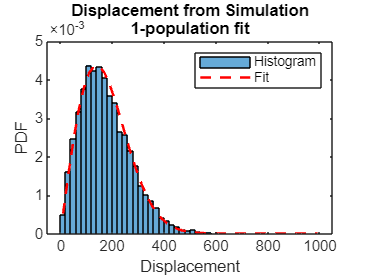


[p_simu_dom,p_fit_dom,simu_result_dom,exp_result_dom,f1,f2] =...
    In_Nuc_fit(Step_in_Domain_simu,Step_in_Domain,...
    pop_domain_ratio,slack_d,slack_acc);

SaveFigure(result_folder,strcat(Domain_name, ' fit from simulation'),...
    f1, {'fig','png','svg'},[])

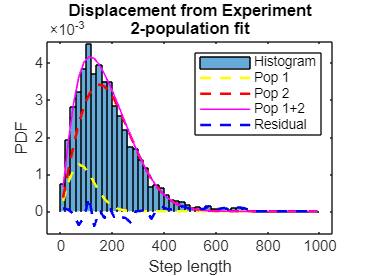

SaveFigure(result_folder,strcat(Domain_name, ' fit from experiment'),...
    f2, {'fig','png','svg'},[])


p_dom_fit_ci = In_Nuc_fit_ci(Step_in_Domain,p_fit_dom);

%  Comparison with inputs / 1-population result
shift_domain = struct( ...
    'InputDomRatio' , pop_domain_ratio      , ...
    'FitDomRatio'   , p_fit_dom(1)           , ...
    'delta_DomRatio', abs(p_fit_dom(1)-pop_domain_ratio) , ...
    'a_simulation'   , p_simu_dom(1)          , ...
    'a_fit'          , p_fit_dom(4)           , ...
    'delta_a_domain'   , abs(p_fit_dom(4)-p_simu_dom(1))/p_simu_dom(1));

% Physical properties derived from the fit
Diff_domain_um2s = p_fit_dom(2) / (4*delta_t) * 1e-3;            % µm²/s
Vis_domain    = 1.380649e-23*temp_K / (6*pi*probe_radius* ...
                   Diff_domain_um2s * 1e-12) * 1e3;          % cP
Vis_domain_lb = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_dom_fit_ci(2)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)
Vis_domain_ub = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_dom_fit_ci(1)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)

Viscosity_domain = struct(...
    'Domain_outline',    Domain_outline,...
    'DomainRatio',       pop_domain_ratio,...
    'Fitting_tolerance', [slack_d,slack_acc],...
    'DiffCoeff_um2_s',  Diff_domain_um2s,...
    'DomainVis',          Vis_domain,...
    'DomainVis_lb',       Vis_domain_lb,...
    'DomainVis_ub',       Vis_domain_ub);

% print
fprintf('\n-----------  Fitting Diagnostics  -----------\n');


-----------  Fitting Diagnostics  -----------


fprintf(strcat(Domain_name, ' pop ratio (input)   : %6.3f\n'), shift_domain.InputDomRatio);

Terminus pop ratio (input)   :  0.118


fprintf(strcat(Domain_name, ' pop ratio (fit)     : %6.3f\n'), shift_domain.FitDomRatio);

Terminus pop ratio (fit)     :  0.153


fprintf('Δ_Domain_ratio = %4.3f ; slack_pop_ratio = %4.3f\n', shift_domain.delta_DomRatio,slack_acc)

Δ_Domain_ratio = 0.035 ; slack_pop_ratio = 0.075



fprintf('\na  (simulation, 1-pop)   : %2.2f\n', shift_domain.a_simulation);


a  (simulation, 1-pop)   : 38460.60


fprintf('a_fit  (fit, 2-pop)      : %2.2f   \n', shift_domain.a_fit);

a_fit  (fit, 2-pop)      : 45364.42   


fprintf('Δ_a  = %5.2f %% ; slack_acc  = %5.2f %%\n', shift_domain.delta_a_domain*100, slack_d*100)

Δ_a  = 17.95 % ; slack_acc  = 18.00 %



fprintf('\n-----------  Physical Properties  -----------\n');


-----------  Physical Properties  -----------


fprintf(strcat('D_', Domain_name, '  (µm²/s)           : %.3e\n'), Diff_domain_um2s);

D_Terminus  (µm²/s)           : 6.741e-02


fprintf(strcat(Domain_name, ' Viscosity (cP)  : %.2f\n'),   Vis_domain);

Terminus Viscosity (cP)  : 263.40


fprintf('Lower bound = %.2f; Upper bound = %.2f\n', Vis_domain_lb, Vis_domain_ub)

Lower bound = 228.39; Upper bound = 311.29


fprintf('----------------------------------------------\n');

----------------------------------------------


Save results

clear f1 f2  slack_d slack_acc
clear pop_domain_ratio Diff_domain_um2s 
clear Vis_domain Vis_domain_lb Vis_domain_ub
clear coord_in_ori Domain_outline DomCoord
clear p_fit_dom p_dom_fit_ci p_simu_dom
clear exp_result_dom simu_result_dom
clear Step_in_Domain Step_in_Domain_simu

Constants = struct(...
    'FrameInterval',     delta_t,...
    'Temperature',       temp_K,...
    'ProbeRadius',       probe_radius);

save(fullfile(result_folder,strcat('Vis',Domain_name,'.mat')), ...
    'Constants', ...
    'Viscosity_domain', ...
    'shift_domain', ...
    '-v7');             % v7.3 for large file
clear Constants Viscosity_domain shift_domain 
fprintf('\n %s Viscosity saved to %s\n',...
    Domain_name, fullfile(result_folder,strcat('Vis',Domain_name,'.mat')));


 LeftArm Viscosity saved to L:\MIGRATED\Lab_Members\Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\Dataset\LAM022_24h_NanocageTracking_withHeater\Result_2025_08_05\VisLeftArm.mat


clear Domain_name